# Sample 3-2

## 平滑化／先鋭化処理

移動平均とラプラシアン 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image smoothing/sharpening

Moving averages and Laplacian

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 処理画像の準備

(Preparation of sample image)

本サンプルで利用する画像データを収めたdata フォルダにパスをとおす。

Create a path to the data folder that contains images used in this sample.

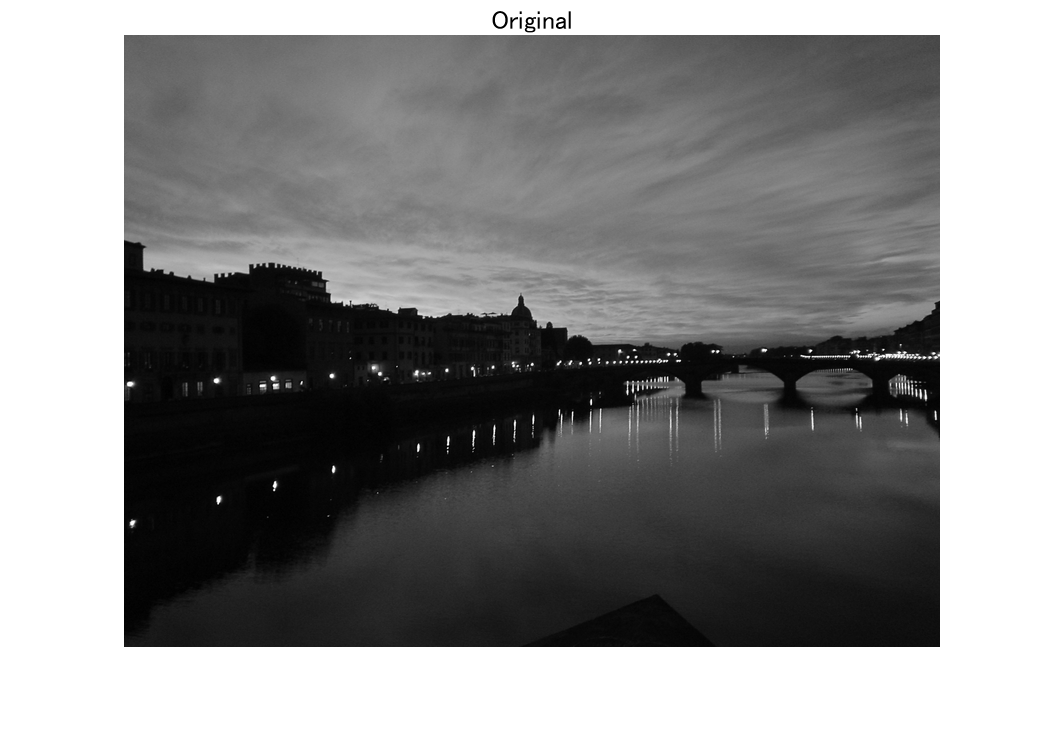

addpath('./data')
close
% Reading original image
I = im2double(rgb2gray(imread('firenzeRgb.jpg')));
imshow(I)
title('Original')

### 移動平均フィルタ

(Moving average filter)

以下に$3\times 3$サイズの平均値カーネルを示す。

(The averaging kernel of size $3\times 3$is shown below.)


$$\mathbf{f}=\frac{1}{9}\left(\begin{array}{ccc}
1 & 1 & 1 \\
1 & 1 & 1 \\
1 & 1 & 1
\end{array}\right)$$


### ガウシアンフィルタ

(Gaussian filter)

$3\times 3$ サイズのガウシアンフィルタの定義を以下に示す。

(The definition of a Gaussian filter of size $3\times 3$ is given below.)


$$\mathbf{f}=\frac{1}{\sum_{j=-1}^{1}\sum_{i=-1}^{1}g(i,j)}\left(\begin{array}{ccc}
g(-1,-1) & g(-1,0) & g(-1,1) \\
g(0,-1) & g(0,0) & g(0,1) \\
g(1,-1) & g(1,0) & g(1,1)
\end{array}\right),$$


ただし，$\sigma$ を標準偏差として

(where let $\sigma$ be a standard deviation and )


$$g(p_1,p_2)=\exp\left(-\frac{p_1^2+p_2^2}{2\sigma^2}\right).$$


### ラプラシアンフィルタ

(Laplacian filter)

以下に4近傍ラプラシアンカーネルを示す。

(The four neighborhood Laplacian kernel is  shown below.)


$$\mathbf{f}=\left(\begin{array}{ccc}
0 & 1 & 0 \\
1 & -4 & 1 \\
0 & 1 & 0
\end{array}\right)$$


### アンシャープマスクフィルタ

(Unsharp mask filter)

以下に4近傍ラプラシアンカーネルを示す。

(The four neighborhood Laplacian kernel is  shown below.)


$$\mathbf{f}=\left(\begin{array}{ccc}
0 & -1 & 0 \\
-1 & 5 & -1 \\
0 & -1 & 0
\end{array}\right)$$


### ソーベルフィルタ

(Sobel filter)


$$\mathbf{f}=\left(\begin{array}{ccc}
1 & 0 & -1 \\
2 & 0 & -2 \\
1 & 0 & -1
\end{array}\right)$$



$$\mathbf{f}=\left(\begin{array}{ccc}
1 & 2 & 1 \\
0 & 0 & 0 \\
-1 & -2 & -1
\end{array}\right)$$


© Copyright, Shogo MURAMATSU, All rights reserved.